clear 
clc

serialportlist

ans = "COM3"

baudrate = 115200;
% data_in = zeros();

s = serialport("COM3",baudrate)

s =   Serialport - 属性:

                 Port: "COM3"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions




data = read(s,4*8192,'uint8')

data =      0     0     5   233     0     0     5   231     0     0     5   230     0     0     5   233     0     0     5   231     0     0     5   231     0     0     5   233     0     0     5   234     0     0     5   234     0     0     5   231     0     0     4   195     0     0     5   233     0     0


% configureTerminator(s,"CR")  
% configureCallback(s,"terminator",@serial_callback) 
% configureCallback(s,"byte",1 ,@serial_callback)
% pause 
% data_serial = zeros()

if (s.NumBytesAvailable == 0)
    disp("Data reading from Serial Port Ready!")
end

Data reading from Serial Port Ready!


## 串口数据后处理

% 将uint8 -> dec 
% data_origin = dec2bin(s.UserData); 
data_origin = dec2bin(data);
data_tag = data_origin(:,1:2);


if (sum(mod(find(data_tag=='11'), 4)) > 0 )
    disp("Data Missing!");
    index = find(data_tag == '11');
    index_mod = mod(index, 4);
    fprintf("Missing data occured at %d sampled point;\n",find(index_mod ~= 0, 3))
    
else
    disp("Data Right!");
end

Data Right!


clear s;

data_sign = str2num(data_origin(:,3));
data_value = data_origin(:,4:end);

data_sign(data_sign==1) = -1;
data_sign(data_sign==0) = 1;
data_value = bin2dec(data_value) .* data_sign;

N_Sample = length(data_value) / 4;
data_N4 = reshape(data_value, [4, N_Sample])'

data_N4 =      0     0     5    -9
     0     0     5    -7
     0     0     5    -6
     0     0     5    -9
     0     0     5    -7
     0     0     5    -7
     0     0     5    -9
     0     0     5   -10
     0     0     5   -10
     0     0     5    -7


## Calibration

gain_rcd = deltaGain(data_N4(:,2:end), 10)

gain_rcd =    15.3040
   15.2996
   15.3061
   15.3061
   15.3061
   15.3133
   15.3111
   15.3111
   15.3033
   15.3061


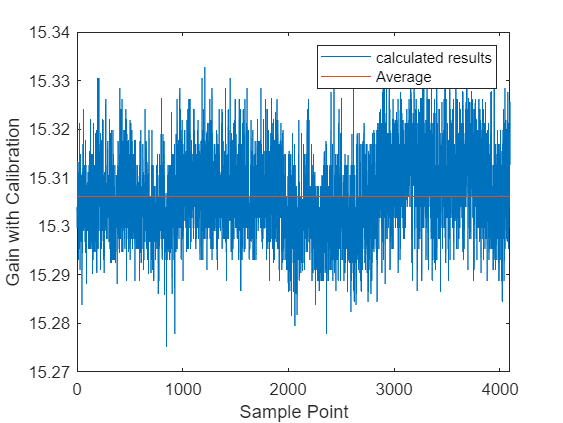

GAIN = mean(gain_rcd);

figure
plot(gain_rcd);
hold on 
plot(ones([1,N_Sample/2])*GAIN)
hold off;
xlim([0, N_Sample/2]);

legend(["calculated results", ...
    "Average"], ...
    'Location', 'northeast')
xlabel("Sample Point");
ylabel("Gain with Calibration");

## Noise Analysis

Vref = 1.8;
N_SUB = 5;
LSB_SUB = 1.8 / 2^N_SUB;

fclock = 50E6 / 1;           % clk_adc = 10kHz;
fprintf("Number of Sample Points: 64 *  16 tiems average;")

Number of Sample Points: 64 *  16 tiems average;

fs = fclock / 25                % sample rate = 200Hz;

fs = 2000000

fin = 1/256*fs                   % fin = 5/64*fs;

fin = 7.8125e+03

Vout_N4 = data_N4 * LSB_SUB

Vout_N4 =          0         0    0.2812   -0.5062
         0         0    0.2812   -0.3937
         0         0    0.2812   -0.3375
         0         0    0.2812   -0.5062
         0         0    0.2812   -0.3937
         0         0    0.2812   -0.3937
         0         0    0.2812   -0.5062
         0         0    0.2812   -0.5625
         0         0    0.2812   -0.5625
         0         0    0.2812   -0.3937


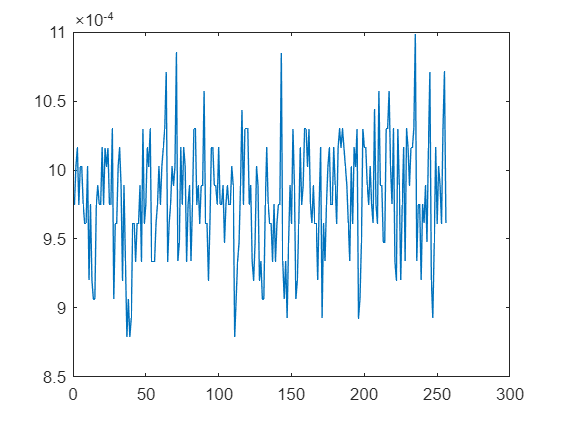


Vout_without_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_without_calib(i) = Calib_Gain(Vout_N4(i,:), 16);
end
plot(Vout_without_calib(1:256,1));

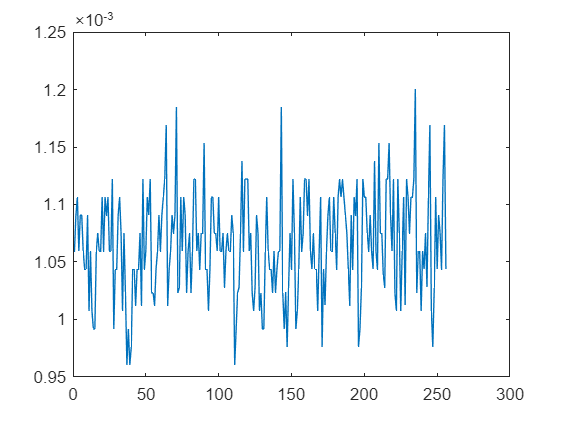

% sinad(Vout_without_calib, fs)
% thd(Vout_without_calib, fs)

% ~~~~~~~~~~~~~~~ mean calibration ~~~~~~~~~~~~~~~
Vout_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_calib(i) = Calib_Gain(Vout_N4(i,:), GAIN);
%     Vout_mean_calib(i) = Calib_Gain(Vout_N4(i,:), 15.4);
end
plot(Vout_calib(1:256,1));

% sinad(repmat(Vout_calib,[1 1]), fs)
% thd(Vout_calib , fs, 9, 'aliased')
% sfdr(Vout_calib, fs)

% noise = Vout_calib;
noise = Vout_without_calib;
Noise_RMS = pow2db(var(noise))

Noise_RMS = -87.2069


% Periodgram

[pxx_1, f] = periodogram(noise, ...
        rectwin(N_Sample), N_Sample, fs, 'PSD');
pxx_1(1)=  0;
pow2db(sum(pxx_1 * (fs/N_Sample)) )

ans = -87.2075

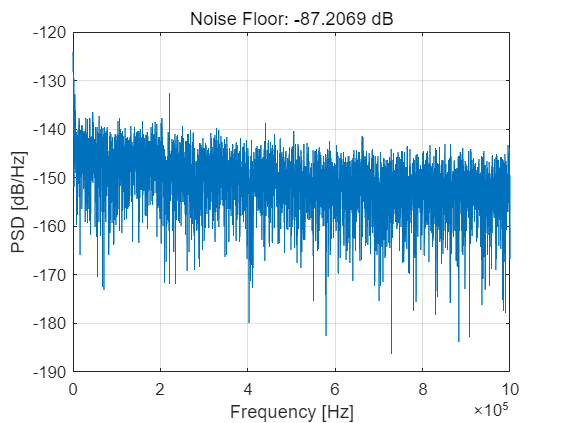

figure
plot(f, 10*log10(pxx_1));
xlabel('Frequency [Hz]');
ylabel('PSD [dB/Hz]')
grid on
title(['Noise Floor: ', num2str(Noise_RMS), ' dB'])

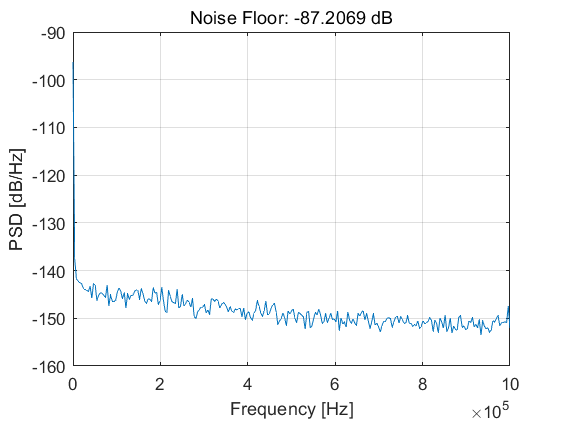


num_sec = 16;
length_sec = N_Sample / num_sec;
pxx_array = zeros(length_sec/2+1, num_sec);
for i=1:num_sec
    index_head = (i-1)*length_sec+1;
    index_tail = i*length_sec;
    noise_temp_sec = noise(index_head:index_tail);
    [pxx_temp, f] = periodogram(noise_temp_sec, ...
        rectwin(length_sec), length_sec, fs, 'PSD');
    pxx_array(:, i) = pxx_temp;
end
pxx_ave = mean(pxx_array,2);
figure
plot(f, 10*log10(pxx_ave));
xlabel('Frequency [Hz]');
ylabel('PSD [dB/Hz]')
grid on
title(['Noise Floor: ', num2str(Noise_RMS), ' dB'])

pxx_ave(1) = 0;
pow2db(sum(pxx_ave * (fs/length_sec)) )

ans = -87.6729

## Display Noise

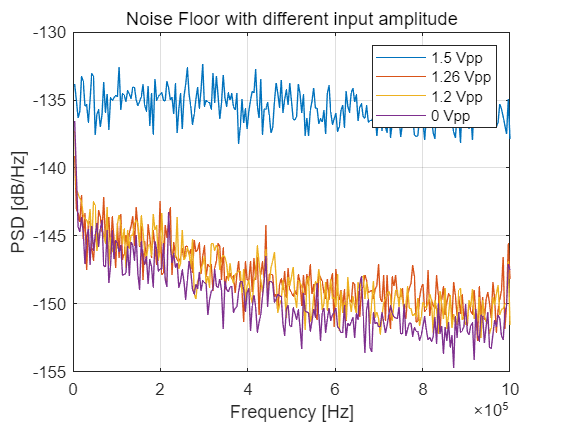

Y_wiclb = [pxx_ave_1V5_wiclb, pxx_ave_1V26_wiclb, ...
    pxx_ave_1V2_wiclb, pxx_ave_0V_wiclb];
Y_woclb = [pxx_ave_1V5_woclb, pxx_ave_1V26_wiclb, ...
    pxx_ave_1V2_woclb, pxx_ave_0V_woclb];
noise_floor_wiclb = pow2db(sum(Y_wiclb .* (fs/length_sec)) );
noise_floor_woclb = pow2db(sum(Y_woclb .* (fs/length_sec)) );

figure
% subplot(2,1,1)
plot(f, 10*log10(Y_wiclb));
xlabel('Frequency [Hz]');
ylabel('PSD [dB/Hz]')
grid on
title(['Noise Floor with different input amplitude'])
legend(["1.5 Vpp" , "1.26 Vpp", "1.2 Vpp", "0 Vpp"]);

% subplot(2,1,2)
% plot(f, 10*log10(Y_woclb));
% xlabel('Frequency [Hz]');
% ylabel('PSD [dB/Hz]')
% grid on
% title(['Noise Floor with different input amplitude'])
% legend({'1.5 Vpp'; '1.26 Vpp'; '1.2 Vpp'; '0 Vpp'});

